close all
clear variables

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

spectra = importdata ("spectra.csv"); 
lambdaStart = importdata ("lambda_start.csv");
lambdaDelta = importdata ("lambda_delta.csv");
starNames = importdata ("star_names.csv");

number_of_measurements = size (spectra, 1)

number_of_measurements = 357

number_of_stars = size (spectra, 2)

number_of_stars = 7

lambda_end = lambdaStart + (number_of_measurements - 1) * lambdaDelta

lambda_end = 679.8600

lambda = (lambdaStart : lambdaDelta : lambda_end)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800


[min_spectras, i_min_spectras] = min(spectra);
i_min_spectras = i_min_spectras'

i_min_spectras =    188
   187
   188
   189
   189
   191
   185


min_spectras = min_spectras'

min_spectras = 	1.0e+-12 *

    0.1634
    0.0724
    0.0314
    0.0536
    0.0690
    0.0980
    0.0221


z = lambda (i_min_spectras) / lambdaPr - 1

z = 	1.0e+-3 *

   -0.1219
   -0.3352
   -0.1219
    0.0914
    0.0914
    0.5181
   -0.7619


speed = z * speedOfLight % Скорость звезд в м/с

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029



movaway = starNames (z > 0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


fg1 = figure;

xlabel ('Длина волны, нм');

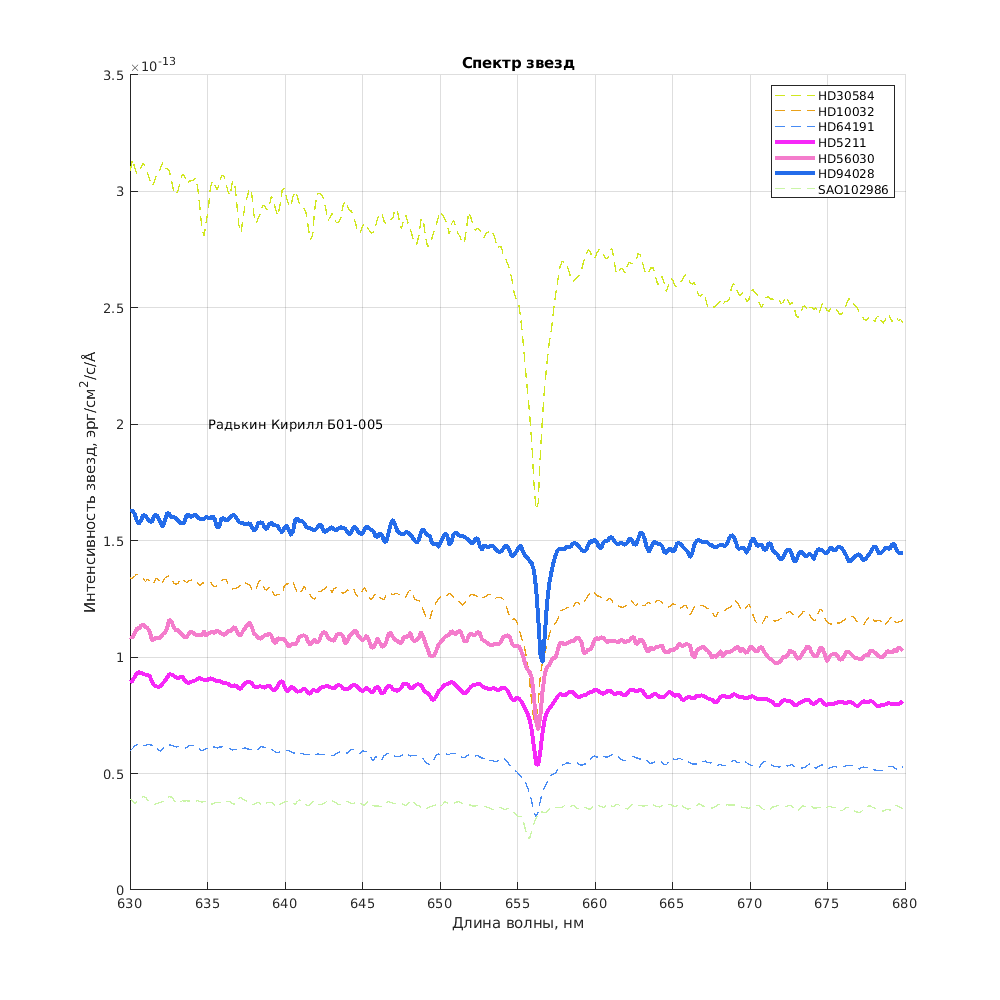

ylabel (['Интенсивность звезд, эрг/см^2/c/', char (197)]);
title ('Спектр звезд');

set (fg1, 'Position', [0, 0, 1000, 1000])

grid on

hold on
for i = 1: 1 : number_of_stars
    if (z(i) >  0)
        plot (lambda, spectra (:, i),'r', 'LineWidth', 3, 'Color', [rand, rand, rand])
    else
        plot (lambda, spectra (:, i), "b--", 'LineWidth', 1, 'Color', [rand, rand, rand])
    end
end

legend (starNames)

text (635, 2 * 10^(-13), "Радькин Кирилл Б01-005")

hold off

saveas (fg1, "spectry.png")